**0. Preparation**

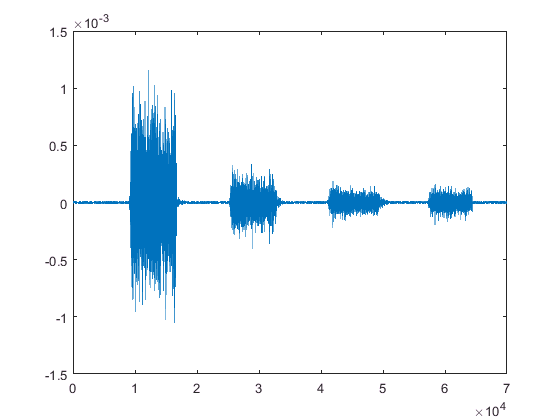

clear,close all,clc

raw = load('Channel1.txt');

raw = raw(1:70000);

% Preview
plot(raw)

**1. Obtain results of RMS-differece **

            RMS - difference - 

            1    2    3    4    5    6    7    8    9    10

haar

sym8

sym5

db5

db2

coif5

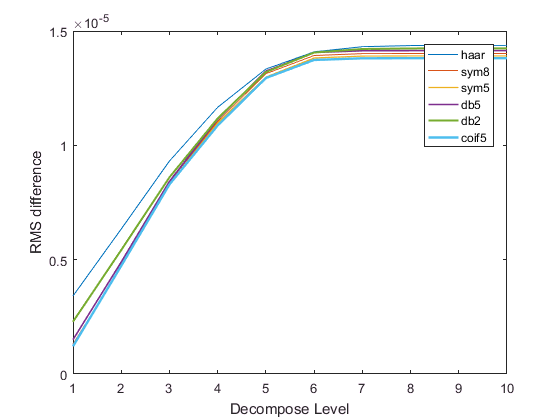

wname = {'haar', 'sym8', 'sym5', 'db5', 'db2', 'coif5'};

rms_results = [];
SNR_results = [];
for nl=1:10 % level
    rms_column_result = [];
    SNR_column_result = [];
    for nw=1:length(wname)
        raw_d = wden(raw, 'minimaxi', 's', 'mln', nl, wname{nw});
        rms_column_result = [rms_column_result; ...
                         rms(raw-raw_d)];
        SNR_column_result = [SNR_column_result; ...
                             10*log10(var(raw)/var(raw-raw_d))];
    end
    rms_results = [rms_results, rms_column_result];
    SNR_results = [SNR_results, SNR_column_result];
end
figure;
for n=1:size(rms_results,1)
    plot(rms_results(n,:), 'linewidth', n*0.3);hold on;
end
xlabel('Decompose Level');
ylabel('RMS difference');
legend(wname)

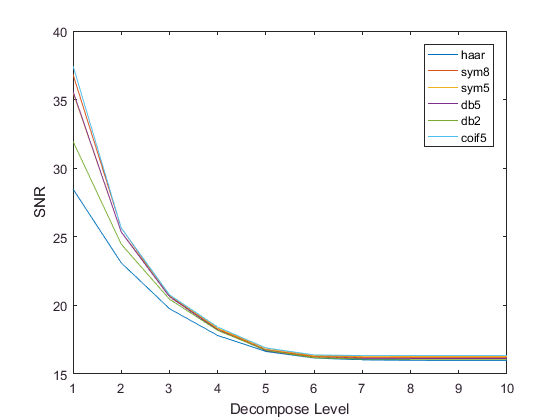

figure;for n=1:size(SNR_results,1)
    plot(SNR_results(n,:));hold on;
end
xlabel('Decompose Level');
ylabel('SNR');
legend(wname)

**3. MSE(mean squared error) of Wavelet coefficients**

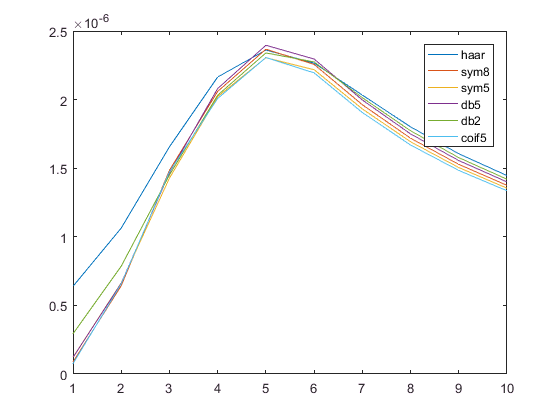

MSE_results = [];

figure;
for nw=1:length(wname)
    MSE = MSE_calculation(raw, wname{nw}, 10);
    MSE_results = [MSE_results; MSE];
    plot(MSE,'linewidth', n*0.3); hold on;
end
legend(wname)